# Safety Critical System Assignment 3, Fault Detection with CUSUM and ARL

clear all; clc;

## Question 1

Generate a random process of 1,000 samples of $\mathcal{N}(1, 1^2)$ and 500 samples of $\mathcal{N}(0.5, 1^2)$

mu0 = 1;
sigma0 = 1;
z0 = normrnd(mu0, sigma0, [1000, 1]);

mu1 = 0.5;
sigma1 = 1;
z1 = normrnd(mu1, sigma1, [500, 1]);

z = [z0; z1];
plot(z)

## Question 2a & 3

Implement CUSUM in an offline manner, i.e., signal length is known in advance.

Since both processes are Gaussian with identical, unitary variance, the cumulative sum is given in lecture note (chapter 7, example 12, page 55)


$$S(k) = \sum_{i=1}^{k}\frac{[z(k) - \mu_0]^2-[z(k)-\mu_1]^2}{2\sigma^2}$$


alongside the decision function $g(k) = S(k) - \min_{1 \leq j \leq k}S(j)$

S = ((z - mu0).^2 - (z - mu1).^2)/2;
cusum = cumsum(S);
g = cusum - cummin(cusum);

%% You can replace those MATLAB built-in functions with a for loop
% cusum = zeros(1,1500);
% g = zeros(1,1500);
% for k = 1:1:1500
%     d0 = (z(1:k) - mu0).^2;
%     d1 = (z(1:k) - mu1).^2;
%     d = (d0 - d1)/2;
%     cusum(k) = sum(d);
%     g(k) = cusum(k) - min(d(1:k));
% end

Handpick the threshold $h$ based on the decision value plot, i.e., $h = 6$. As a result, the fault is introduced at $k=1,001$ but only detected at $k_{detected}$

h = 6;
k_detected = find(g >= h, 1) % aka. 'Alarm time'

k_detected = 1033

In the offline calculation, the fault occurence time $n_c$ is estimated to be from $k_{detected}$ onward.

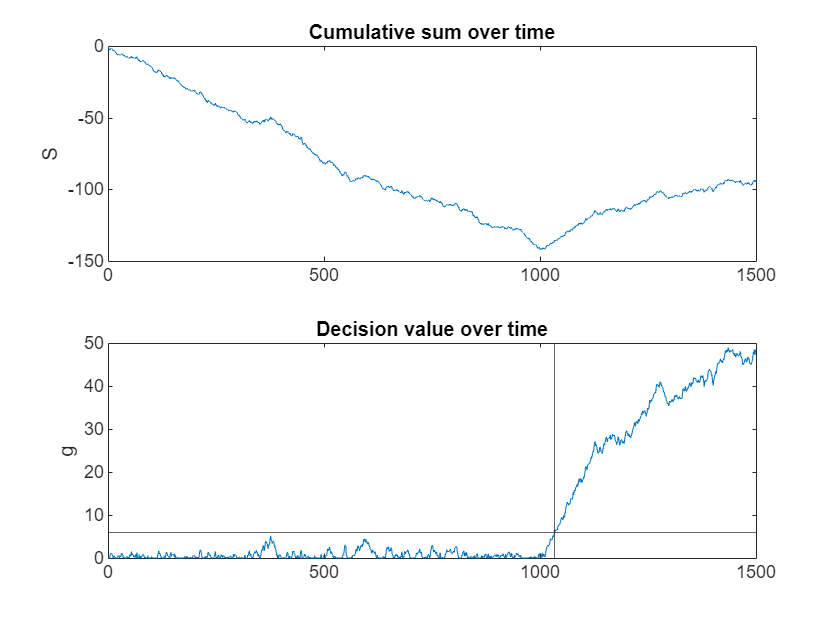

% Plot the results
figure;

% Plot the first array in the first subplot
subplot(2, 1, 1);
plot(cusum);
title('Cumulative sum over time');
ylabel('S');

% Plot the second array in the second subplot
subplot(2, 1, 2);
plot(g);
yline(h);
xline(k_detected);
title('Decision value over time');
ylabel('g');

## Question 2b

Implement CUSUM in a recursive manner, i.e., signal length is unknown. The step-by-step increment of CUSUM is given in the lecture


$$s(x_k) = \frac{\mu_1 - \mu_0}{\sigma^2}(x_k - \frac{\mu_1 - \mu_0}{2})$$


Again, note that this only applies when both processes have the same variance.

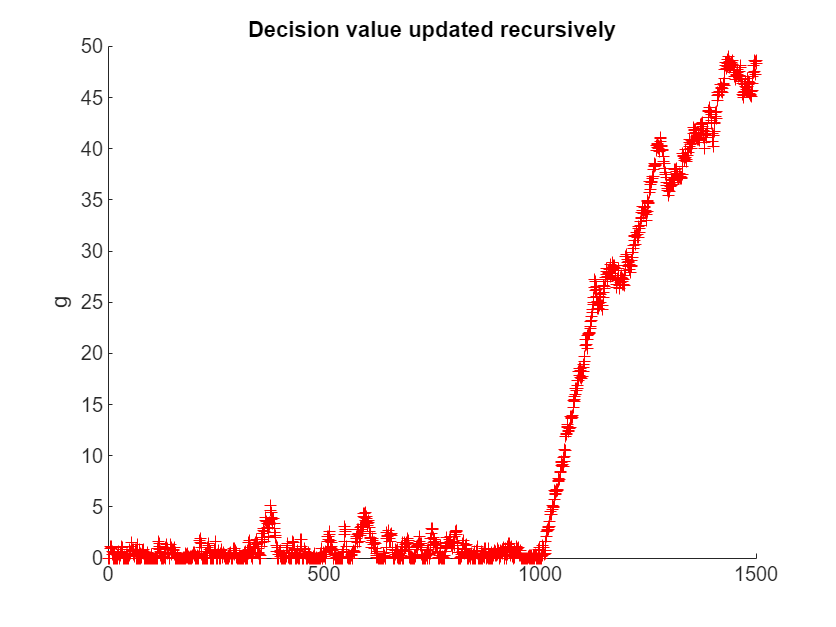

figure;
hold on;
title("Decision value updated recursively");
ylabel('g');

k = 1; % Discrete time
g = 0; % Decision value
S = 0; % Cumulative sum
N = 0; % Discrete function that depends on 'g' to estimate fault occurence time
a = (mu1 - mu0)/1^2;
b = (mu1 + mu0)/2;
while true
    try % Looping from 1
        u = z(k);
    catch ME
        if strcmp(ME.identifier, "MATLAB:badsubscript")            
            break % New value unavailable
        end
    end

    s = a*(u - b);
    S = S + s;
    g = max([0, g+s]);
    plotGk = scatter(k, g, '+', 'red');

    k = k+1;
end
hold off;

Reuse the threshold $h=6$ in question 2a to get the same estimated timestamp at which the fault occurs.

## Question 4

Use average runtime length (ARL) 